Here is a forcing function for Poisson's equation.

f = @(x,y) x.^2 - y + 2;

We pick a crude discretization for illustrative purposes.

m = 5;  n = 6;
[X,Y,d] = rectdisc(m,[0 3],n,[-1 1]);

Next, we evaluate $f$ on the grid.

F = f(X,Y);

Here are the equations for the PDE collocation, before any modifications are made for the boundary conditions.

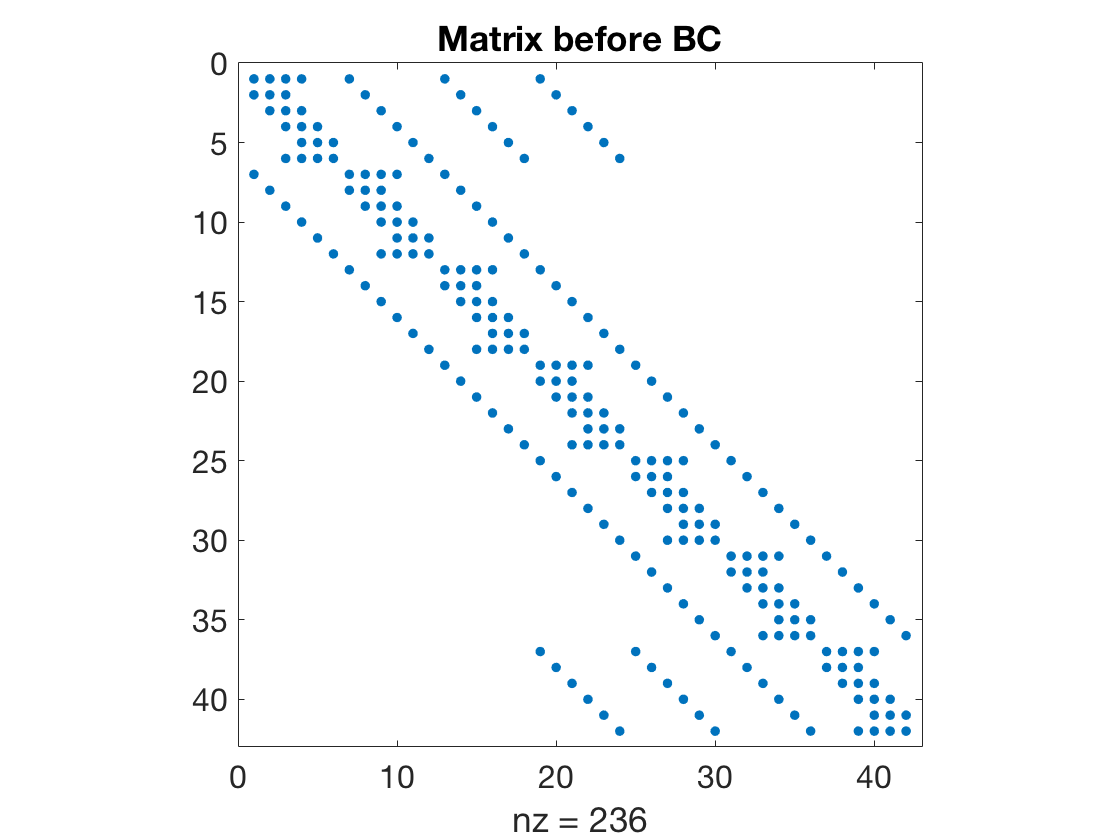

A = kron(d.Iy,d.Dxx) + kron(d.Dyy,d.Ix);
spy(A)
title('Matrix before BC')    % ignore this line

b = d.vec(F);
N = length(b)

N = 42

The array `d.isbndy` is logical and the same size as `X`, `Y`, and `F`.

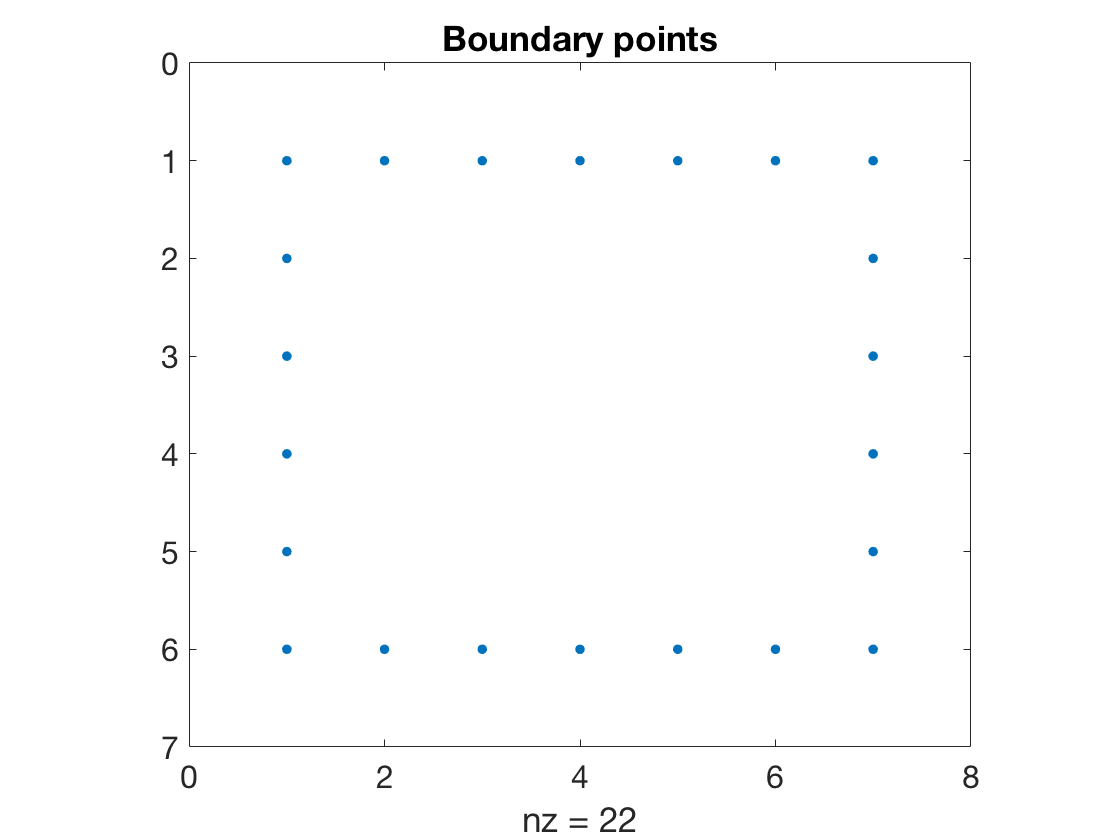

spy(d.isbndy), title('Boundary points')

Next replace the boundary rows of the system by rows of the identity.

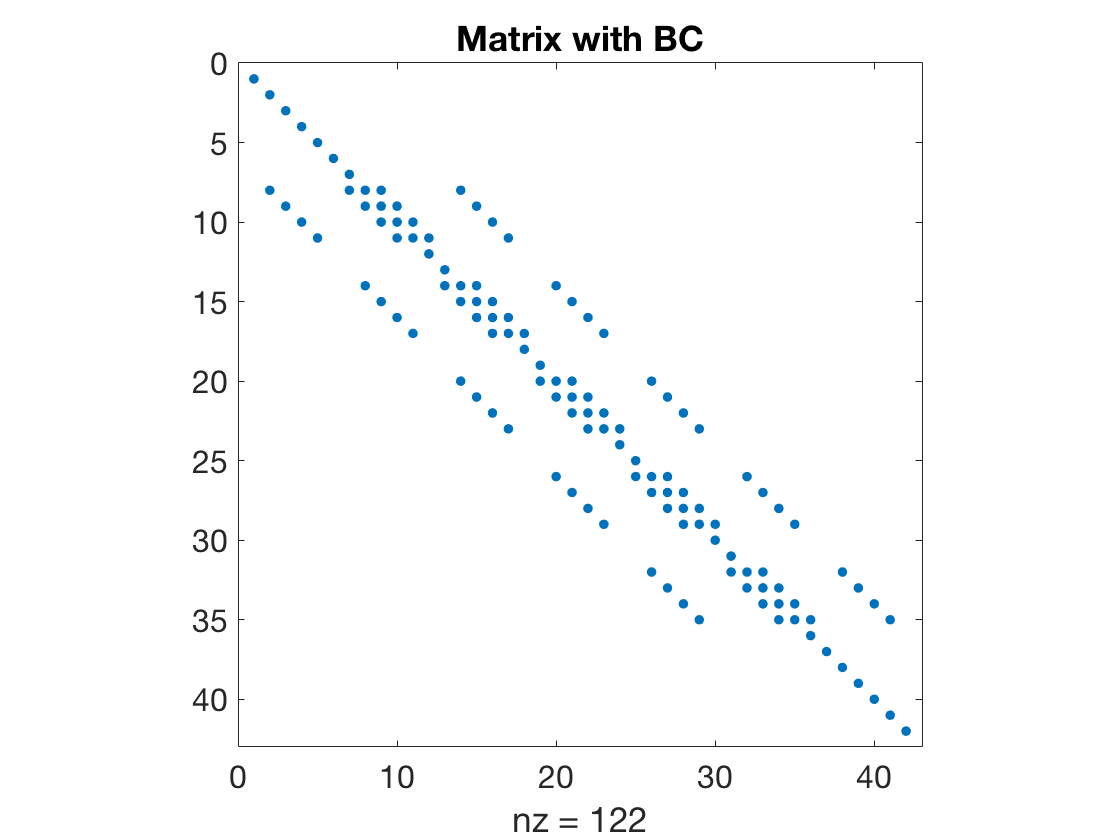

I = speye(size(A));
A(d.isbndy,:) = I(d.isbndy,:);   % Dirichlet conditions
spy(A)
title('Matrix with BC')    % ignore this line

Finally, we must replace the rows in the vector $\mathbf{b}$ by the boundary values being assigned to the boundary points. Here, we let the boundary values be zero everywhere. 

b(d.isbndy) = 0;                 % Dirichlet values

Now we can solve for $\mathbf{u}$ and reinterpret it as the matrix-shaped $\mathbf{U}$, the solution on our grid. This grid is much too coarse for the result to look like a smooth function of two variables.

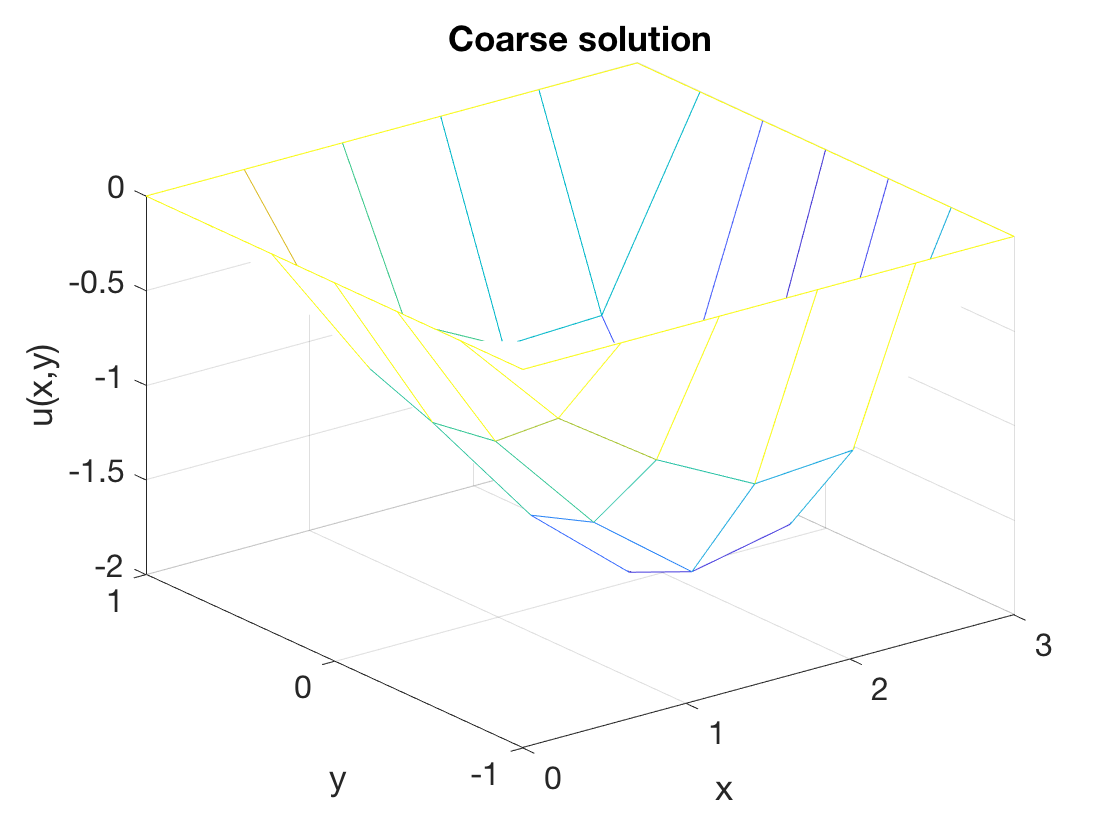

u = A\b;
U = d.unvec(u);
mesh(X,Y,U)
xlabel('x'), ylabel('y'), zlabel('u(x,y)')     % ignore this line
title('Coarse solution')     % ignore this line